**Ejemplo_XOR_A**

Dos entradas x1 y x2

n1 = x1 or x2 

n2 = x1 nand x2

n3 = n1 and n2

Finalmente tenemos que n3 realiza la operacion XOR  

x1 = 1

x1 = 1

x2 = 1

x2 = 1

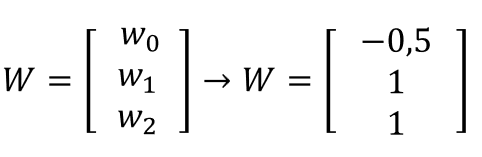

w1 = [-0.5 ; 1 ; 1]     % Pesos de la compuerta OR

w1 =    -0.5000
    1.0000
    1.0000


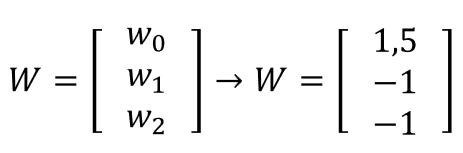

w2 = [1.5 ; -1 ; -1]     % Pesos de la compuerta NAND

w2 =     1.5000
   -1.0000
   -1.0000


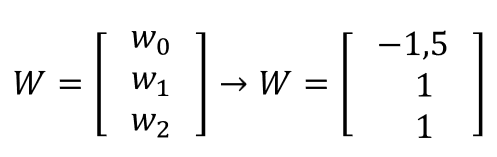

w3 = [-1.5 ; 1 ; 1]     % Pesos de la compuerta AND

w3 =    -1.5000
    1.0000
    1.0000


Definimos el bias, el vector de entrada, fucnion de activacion.

bias = 1

bias = 1

f = 0

f = 0

x = [bias x1 x2]'

x =      1
     1
     1


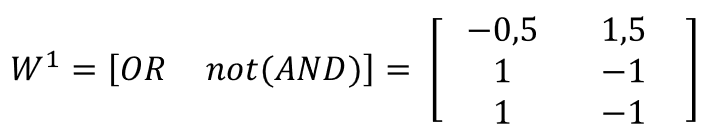

W = [w1  w2]

W =    -0.5000    1.5000
    1.0000   -1.0000
    1.0000   -1.0000


Realizamos la operacion entre el vector de entrada y la capa oculta.

y = (W' * x)

y =     1.5000
   -0.5000


y = y >= f

y = 2×1 logical array
   1
   0


Creamos el vector de enetrada para la capa de salida.

xo = [bias ; y]

xo =      1
     1
     0


Realizamos la operacion entre el vector de salida de la capa oculta y la capa salida.

y = (w3' * xo)

y = -0.5000

y = y >= f

y = logical
   0
